# nGaussian Elimination with Backward Substitution

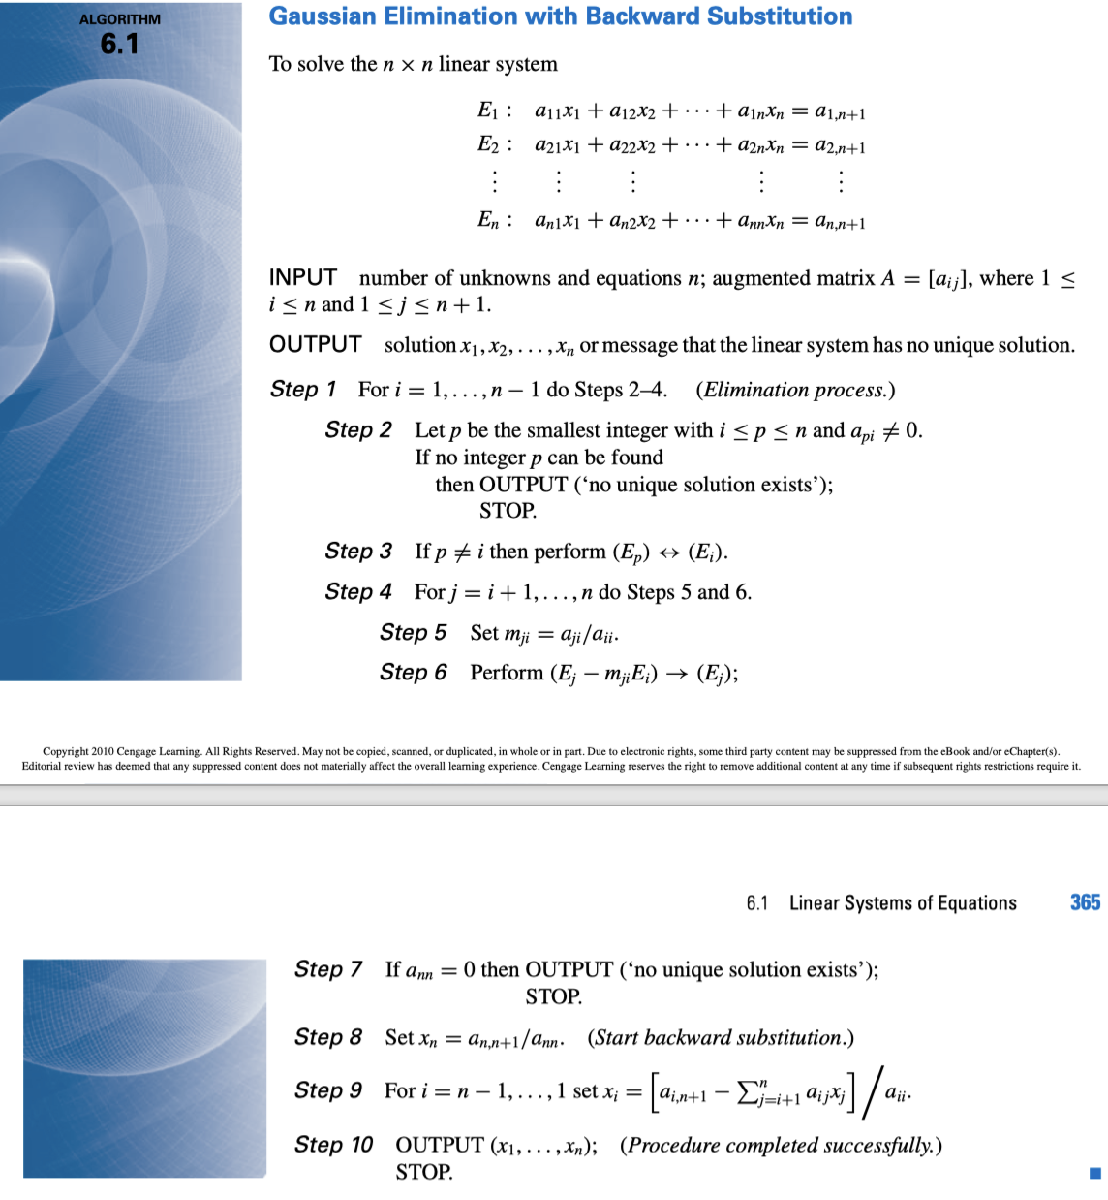

clc;clear;close all;

A=[0,0,-1,1;
    1,1,-1,2;
    -1,-1,2,0;
    1,2,0,2];


rowchange=[];

[Aau,m,rowchange]=uppertriangle(A);
[n,m]=size(A);
P=eye(n);
[r,c]=size(rowchange);
for i=1:r
    Ptemp=P(rowchange(i,1),:);
    P(rowchange(i,1),:)=P(rowchange(i,2),:);
    P(rowchange(i,2),:)=Ptemp;
end


PA=P*A;

[Aau,m,rowchange]=uppertriangle(PA);



L2=eye(n);
L1=zeros(4,4);
L1(2:n,1:n-1)=m(2:end,:);
L=L1+L2;
U=Aau(:,1:n);






function [Aau,m,rowchange]=uppertriangle(Aau)
[n,m]=size(Aau);
rowchange=[];
Ag={};
for i=1:n-1
    %Check and switch to check pivot to be not 0
    p=i;
    while Aau(p,i)==0 & p <= n-1    
        p=p+1;
    end
    if p==n & Aau(p,i)==0
        disp("No unique solution found, please check");
        break
    end

    %record the row exchange
    rowchange=[rowchange;i,p];
    Atemp=Aau(i,:);
    Aau(i,:)=Aau(p,:);
    Aau(p,:)=Atemp;
    for j=i+1:n
        m(j,i)=Aau(j,i)/Aau(i,i);
        Aau(j,:)=Aau(j,:)-m(j,i).*Aau(i,:);
    end
    Ag{i +1}=Aau;
end
end